# LAB 6

Arjun Gandhi, Christian Cooper, Ilyas Salhi

### Introduction

The goal of this lab was to combine everything we learned throughout the term and apply it to a relevant to life example. We have been progressively building on this problem for the last five labs. Bode plots give a method to visualize the gain and phase responses of a given system. A lag compensator reduces lag in the system by increasing the gain at lower frequencies while leaving other frequencies largely unaffected. For the simulink portion, we modeled a two mass spring system to simulate the smooth start and stop of a train

### Part 1

For this part of the lab we modeled a car system previously modeled in other labs, we meaured the steady state error when gain was 1, then found the Kp value so that the steady error was < 2%. we then looked at the frequency response and step response of the system and implement a lag compensator to help with the response at low frequencies

#### Steady State Error Symbolically

clear;
syms s 

m = 1000;
b = 50; 
u = 500;


G = 1/(m*s + b)

$$G = \frac{1}{1000\,s+50}$$


C = 1

C = 1


TF = G*C/(1+G*C)

$$TF = \frac{1}{\left(1000\,s+50\right)\,\left(\frac{1}{1000\,s+50}+1\right)}$$


ss_error = limit(TF/s,s,inf)

$$ss\_error = 0$$

#### Steady State Error Matlab

clear;
close all;
% 𝑚𝑣̇ + 𝑏𝑣 = u
% U(s) = m(V(s)s-v(0)) + bV(s)
% U(s) /s+b) -m(v(0))
% openloop: V(s)/U(s) = 1/(ms+ b)
m = 1000;
b = 50; 
u = 500;


s = tf('s');
G = 1/(m*s + b) %Open loop

G =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.



C = pid(1)

C =
 
  Kp = 1
 
P-only controller.



TF = feedback(G*C,1) % feed back

TF =
 
       1
  -----------
  1000 s + 51
 
Continuous-time transfer function.



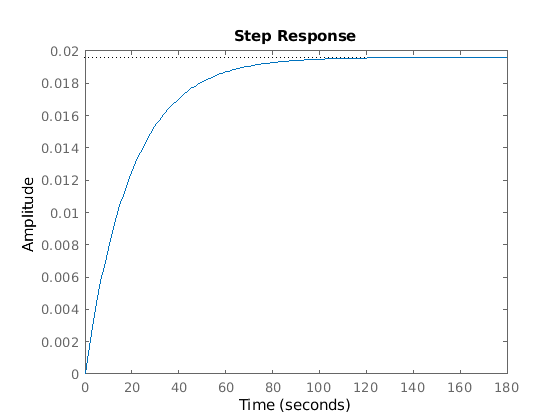


step(TF)

[y,t] = step(TF);
step_info = stepinfo(TF)

step_info = struct with fields:
        RiseTime: 43.0786
    SettlingTime: 76.7073
     SettlingMin: 0.0177
     SettlingMax: 0.0196
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0196
        PeakTime: 206.7812



ss_error_precentage = abs(1-y(end))*100

ss_error_precentage = 98.0395

#### Finding Gain Where ss_error < 2%

kp = 2467

kp = 2467

C = pid(kp)

C =
 
  Kp = 2.47e+03
 
P-only controller.



TF = feedback(G*C,1) % feed back

TF =
 
      2467
  -------------
  1000 s + 2517
 
Continuous-time transfer function.




[y,t] = step(TF);
step_info = stepinfo(TF);

ss_error_precentage = abs(1-y(end))*100

ss_error_precentage = 1.9988

#### Bode  Plot and Step Response

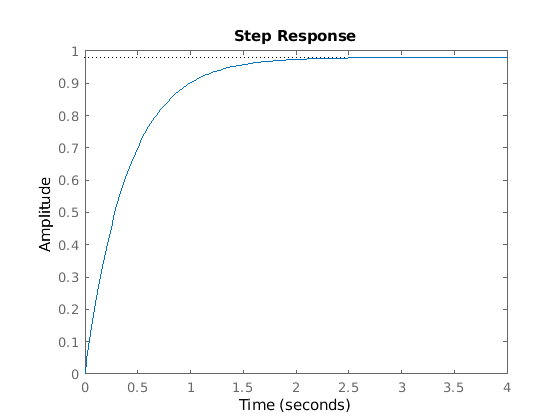

step(TF)

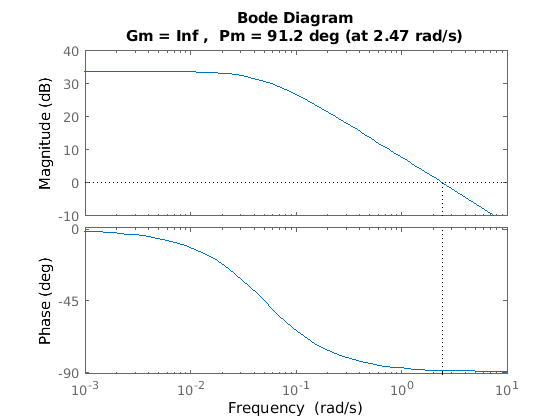

margin(G*C)

This is unacceptable step response

#### Designing a Lag Compensator

z0 = .1

z0 = 0.1000

p0 = .02

p0 = 0.0200

kp = 1000

kp = 1000


C_lag = (s+z0)/(s+p0)

C_lag =
 
  s + 0.1
  --------
  s + 0.02
 
Continuous-time transfer function.



OLTF = kp*C_lag*C*G

OLTF =
 
  2.467e06 s + 246700
  -------------------
  1000 s^2 + 70 s + 1
 
Continuous-time transfer function.



CLTF = feedback(OLTF,1) % feed back

CLTF =
 
       2.467e06 s + 246700
  ------------------------------
  1000 s^2 + 2.467e06 s + 246701
 
Continuous-time transfer function.



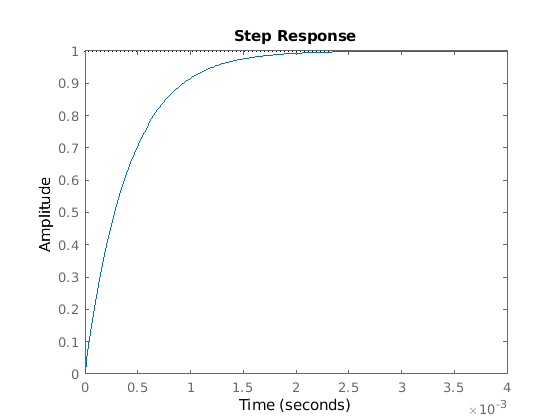


step(CLTF)

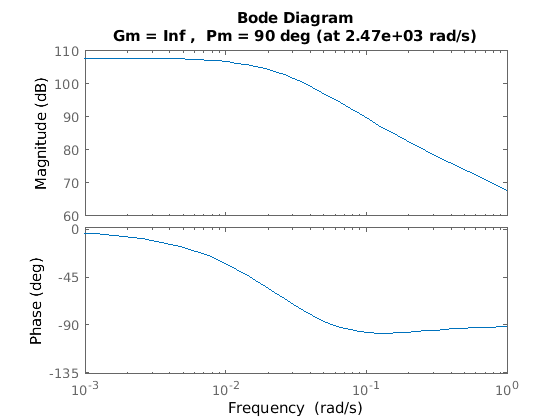

margin(OLTF)

### Part 2

For this potion of the lab we modeled our most complex system this term with a train that could be broken down into two masses attached by a spring. We also played with our first example of a square wave signal generator block and fed back not just the first but also the second derivative of x in each equation back into one summation. We also were able to define paramters from workspace scripts making the titles and labels neat and easy to update. After completing the block diagrams, the two graphs outputted showed x1dot and x2dot and how they grew over time.For this potion of the lab we modeled our most complex system this term with a train that could be broken down into two masses attached by a spring. We also played with our first example of a square wave signal generator block and fed back not just the first but also the second derivative of x in each equation back into one summation. We also were able to define paramters from workspace scripts making the titles and labels neat and easy to update. After completing the block diagrams, the two graphs outputted showed x1dot and x2dot and how they grew over time.

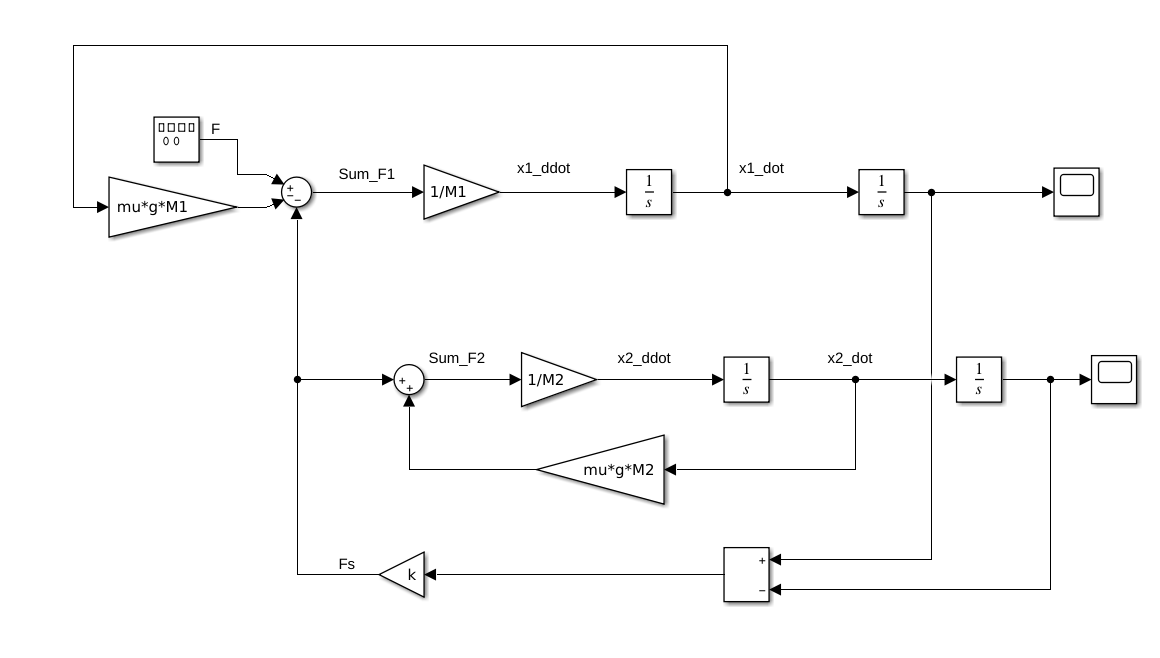

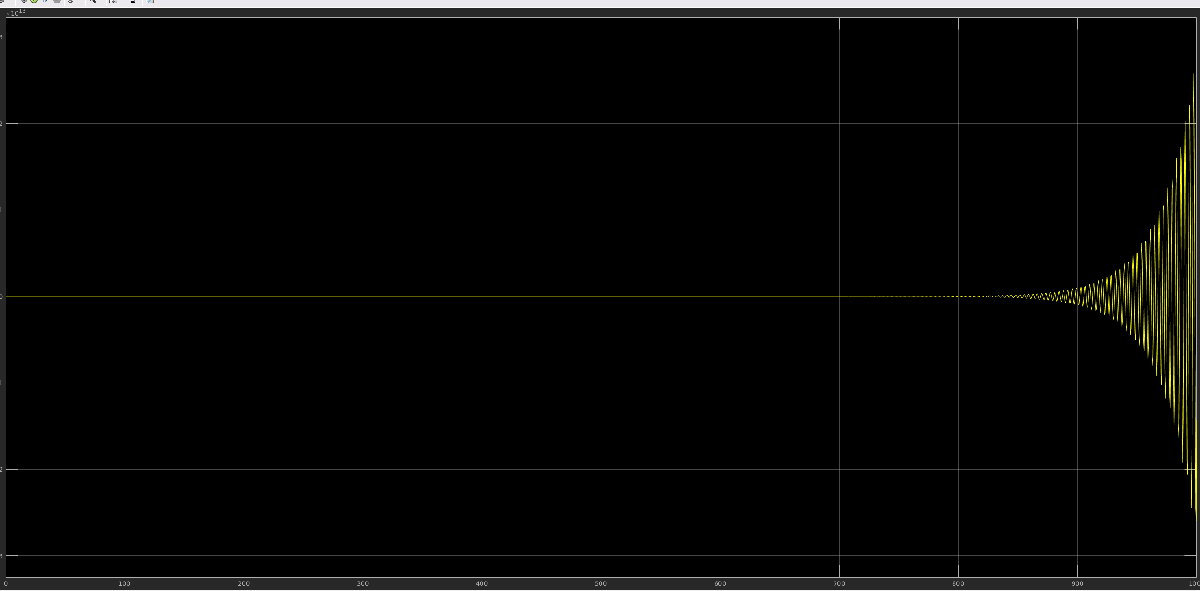

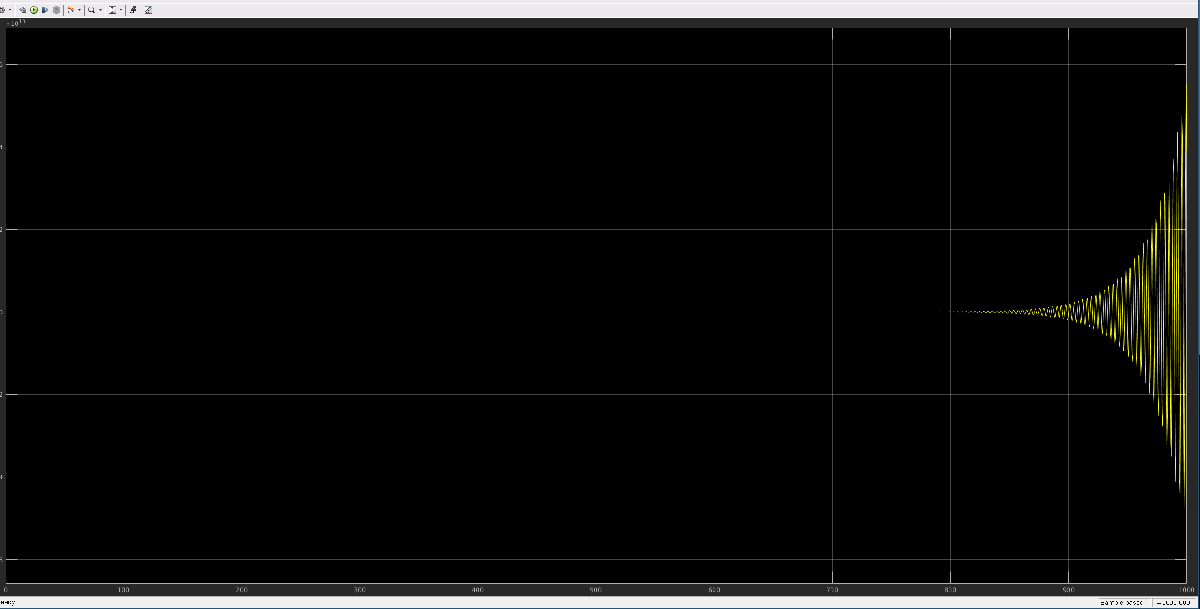

### Conclusion

For this part of the lab we modeled a car system previously modeled in other labs, we meaured the steady state error when gain was 1, then found the Kp value so that the steady error was < 2%. we then looked at the frequency response and step response of the system and implement a lag compensator to help with the response at low frequencies